# Generating Surface Meshes and Calculating Metrics for a subset of dying cells

This script generates cell surface meshes for a set of taste cells that are dying but that have not had their lysosomes segmented. The metrics calculate from these cells will be used to increase our *n* in the statistical analysis of cell size. 

Since these cells do not have their lysosomes, we have not added their information to the idT table or the VL table. Instead, we generate dying cell table: dcT. 

Refer to the [generate_cellMesh_cellT.mlx](matlab:open('./generate_cellMesh_cellT.mlx')) script for more details on cell mesh generation. 

REQUIREMENTS: 

- ManifoldPlus [https://github.com/hjwdzh/ManifoldPlus](https://github.com/hjwdzh/ManifoldPlus) 

- pyMeshFix: [https://pymeshfix.pyvista.org](https://pymeshfix.pyvista.org)

- Mathworks Lidar Toolbox

- MatGeom Toolbox (meshVolume function)

## Set-up

clearvars -except paths
close all
clc

### Path to manifoldPlus

Update manifoldPlus path for your local installation (../ManifoldPlus/build/manifold)

paths.manifoldPlus = "/Users/ernesto/github/ManifoldPlus/build/manifold";

## Load Reconstruct Data

### Get Cell Dying Table

This table contains the names of a series of dying cells

% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts2.Sheet = "Sheet1";
opts2.DataRange = "A2:E12";

% Specify column names and types
opts2.VariableNames = ["ID", "Object", "Type", "Health", "TB"];
opts2.VariableTypes = ["string", "string", "categorical", "categorical", "categorical"];

% Specify variable properties
opts2 = setvaropts(opts2, ["ID", "Object"], "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["ID", "Object", "Type", "Health", "TB"], "EmptyFieldRule", "auto");

% Import the data
dcT = readtable("/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dying_list.xlsx", opts2, "UseExcel", false);

% Clear temporary variables
clear opts2

% Display results
dcT

#### Overlapping cells

The following two cells are found in both datasets. This will need be dealt with

la = ismember(idT.Cell,dcT.Object);

ans = 2×1 string array
    "TB2_TCdying-01_cw"
    "TB2_TCdying-02_cw"


idT.Cell(la)

### Get SL and TL

*series list* and *trace list*

folder_name = "Courtney_TF21"

folder_name = "Courtney_TF21"

paths.series = fullfile(paths.reconstruct, folder_name);
load_last = false; % load last saved file --- faster

[SL, TL] = get_series_contents(paths.series,load_last); % true input means load mat files instead

### Get fTL

*filtered trace list*

- Set the Object names to import. 

- The following objects are all dying cells:

filter_str = dcT.Object;
fTL = filter_trace_list(SL,TL, filter_str,true); % true means exact match
fTL.Properties.Description = 'dying_cells'; % modifies file name to keep projects separate

#### id missing objects

la = ismember(dcT.Object, fTL.Object);
disp(dcT.Object(~la))

- if no output, no missing objects

### get vl

vl = get_verTCs(SL,fTL,true);

VL loaded from File


### Convert to microns

img_mag = vl.Properties.UserData.img_mag;
vl(:,["x","y","z"]) = varfun(@(x) x * img_mag,vl,InputVariables=["x","y","z"]); % convert to microns

## Generate Dying Cell Meshes

- no lysosomes in this dataset

meshT = genDyingCellMesh(vl,dcT, paths);

1. TB2_TCdying01
##################### Arguments #####################
depth: 6.
input: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dyingMeshes/TB2_TCdying01_as.obj.
output: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dyingMeshes/TB2_TCdying01_mp.obj.
#####################################################
vertex number: 16259    face number: 32838
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 1206    
Iter 1 with active vertex number 1206    
Iter 2 with active vertex number 910    
Iter 3 with active vertex number 313    
Iter 4 with active vertex number 222    
Iter 5 with active vertex number 204    
Iter 6 with active vertex number 199    
Iter 7 with active vertex number 182    
Iter 8 with active vertex number 160    
Iter 9 with active vertex number 156    
Iter 10 with active vertex number 143    
Iter 11 with active vertex number 1

disp(meshT)

          ID           Type    Health    VolAS     VolMP     VolFX     Method
    _______________    ____    ______    ______    ______    ______    ______

    "TB2_TCdying01"    x       late      149.89     403.6    403.03     "mp" 
    "TB2_TCdying02"    x       late      249.22    457.08    456.91     "mp" 
    "TB3_TC01"         x       late      246.54    446.93    446.92     "mp" 
    "TB3_TC02"         II      early     797.71    943.65    967.71     "mp" 
    "TB3_TC03"         III     early     1057.5    1310.5    1309.2     "mp" 
    "TB3_TC04"         II      early      333.2      1677    1676.2     "mp" 
    "TB3_TC05"         II      early     546.96    1854.5    1855.2     "mp" 
    "TB3_TC06"         III     early     508.19    1219.7  

### Save MeshT

save(meshT.Properties.UserData.path,"meshT")

## Inspect Cell Meshes

Once **generateCellMeshes** is complete, it is critical to inspect all of the meshes, especially those that have radically different volume calculations between the various methods.  

1. TB3_TC05_as.obj - 0


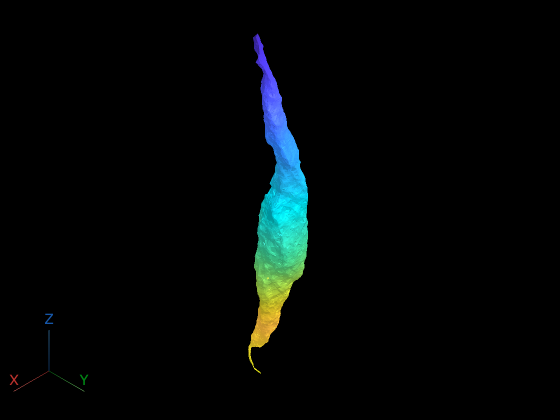

2. TB3_TC05_fx.obj - 0
3. TB3_TC05_mp.obj - 0


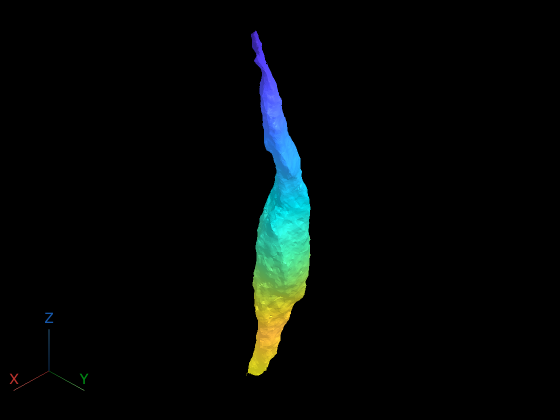

srow = 7;
hvwr = displayCellMeshes(meshT.ID(srow),paths.dyingCellMesh);

- all Cell Dying Cell Meshes appear to be well represented by the MP method

- Copy the meshes 

## Calculate Dying Cell Metrics

### load meshT if needed

load(fullfile(paths.dyingCellMesh,"meshT.mat"),"-mat","meshT")

dyingT = calcCellMetrics(meshT,paths)

### Exclude TB2 rows from analysis

- They will be captured in the ***cellT*** dataset

la_tb2 = contains(meshT.Mesh,"TB2");
dyingT(la_tb2,:) = [];

### save dyingT table

save(dyingT.Properties.UserData.path,"dyingT")

# Local Functions

## Generate Mesh

Also calculates volumes for each mesh

function [meshT] = genDyingCellMesh(vl,dcT, paths)
%GET_CELL_METRICS. Calculates the volume of each cell

arguments
    vl table % vertices list table
    dcT table % dying cell id table
    paths struct % contains project relevant paths
end


% suppress alpha shape warnings
id = 'MATLAB:alphaShape:DupPointsBasicWarnId';
warning('off',id);

% % get string snippet before second underscore (ty chat playground)
% strArray = dcT.Object;
% cellID = strings(size(strArray));
% 
% for i = 1:numel(strArray)
%     parts = strsplit(strArray(i), '_');
%     cellID(i) = strjoin(parts(1:2), '_');
% end

[cellID,ia] = unique(dcT.ID);

% preallocate table
count = numel(cellID);

meshT = dcT(ia,{'ID','Type','Health'});
meshT.Properties.VariableNames(1) = "Mesh";
meshT = [meshT array2table(nan(count,3), 'VariableNames',["VolAS","VolMP","VolFX"])];
meshT.Method = repmat("mp",count,1);

hwb = waitbar(0,"Please Wait");
for n=1:count
    fprintf("%d. %s\n",n,cellID(n))

    mesh_name = cellID(n);
    la = dcT.ID == mesh_name; % returns cell names and bits
    la = ismember(vl.Object,dcT.Object(la));

    vCell = (vl{la,["x" "y" "z"]});
    vCell = realign_vCell(vCell); 
    shp = alphaShape(vCell);

    [volMP, volFX] = getWaterTightMesh(shp,mesh_name, paths,path2use="dyingCellMesh");

    meshT.VolAS(n) = shp.volume;
    meshT.VolMP(n) = volMP;
    meshT.VolFX(n) = volFX;
       
    waitbar(n/count, hwb,sprintf('%d. %s',n,mesh_name))
end
la = meshT.VolAS > meshT.VolFX;% volumes that get smaller indicate increase in raggedness in surface
meshT.Method(la) = "as"; % so, just use the alphaSurface
meshT.Properties.UserData.path = fullfile(paths.dyingCellMesh,"meshT.mat");

delete(hwb)

end

## Realign Vertices to Axes

function vCell = realign_vCell(vCell)
% transform vertices
vCell = vCell - mean(vCell);

[~,~,V]=svd(vCell,0); % Find the direction of most variance
vCell =  vCell * V;

% align to z-axis
% angl = 90 * polarity;
vCell = mmRotateSurfaceVertices(vCell,'y',90);

% rotate around z-axis
vCell = mmRotateSurfaceVertices(vCell,'z',90);
end


## Calculate Cell Metrics

Metrics used in analysis

% function dyingT = calcCellMetrics(meshT,paths)
% 
% dyingT = meshT(:,{'Cell','Type','Health'});
% 
% for n=1:height(meshT)
% 
%     fullpath = fullfile(paths.dyingCellMesh,meshT.Mesh(n)+sprintf('_%s.obj',meshT.Method(n)));
%     mesh = readSurfaceMesh(fullpath);
% 
%     dyingT.Volume(n) = meshVolume(mesh.Vertices, mesh.Faces);
%     dyingT.SurfaceArea(n) = meshSurfaceArea(mesh.Vertices, mesh.Faces);
%     dyingT.SAV(n) = dyingT.Volume(n)./dyingT.SurfaceArea(n);
%     fprintf('%d. %s.\n',n,meshT.Mesh(n))
% 
% end
% dyingT.Properties.UserData.path = fullfile(paths.lysosome,"dyingT.mat");
% 
% end